clear 
close all
clc
% To load the data
%addpath('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab')
%savepath
%dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240408\Results\Basler_acA2040-90uc__21599070__20240408_111238612_0001_diff_new.dat')
dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240522_A3_1\Separate frames\Batch processing\Results\20240522_rot_2.6Hz_9mm_A3_frame_0001A_vel_new.dat');


% Copy dr to dr_new & delete rows and columns with only zeros

dr_new=dr;
%vx=dr.vx;
% Delete zeros for x comp
dr_new.vx(:,all(dr_new.vx == 0,1))=[];
dr_new.vx(all(dr_new.vx == 0,2),:)=[];

dr_new.vy(:,all(dr_new.vy == 0,1))=[];
dr_new.vy(all(dr_new.vy == 0,2),:)=[];


% Compute the surface height

%h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new,h_0);

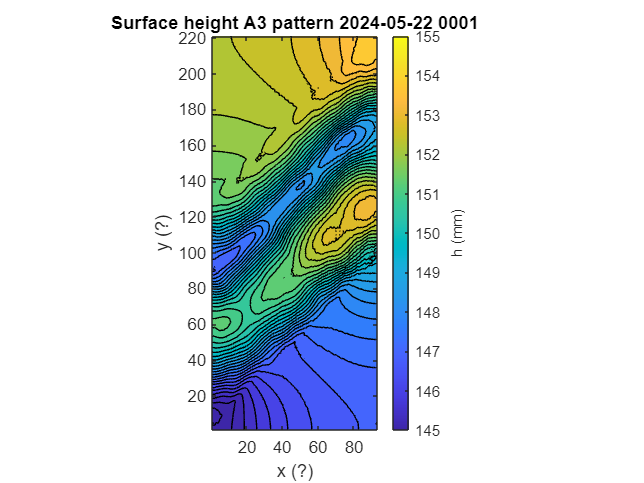

% Plot the surface height & save figure

%surf(h.w)
%showf(h.w)
contourf(h.w, 30);
axis equal
title('Surface height A3 pattern 2024-05-22 0001')
col = colorbar;
xlabel('x (?)');
ylabel('y (?)');
ylabel(col,'h (mm)');
caxis([145, 155]);
%w=h.w
%save('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240522_A3_1 Results\20240408_1112_surface_0001.mat','h')
exportgraphics(gcf,'C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240522_A3_1 Results\20240408_surface_height_0001.png')